# System Studies: Enhance EV Performance via Software Changes Only

*Can I update my 2-Motor EV's software to enhance*

- *Range (decrease energy consumption)*

- *0-60mph time*

*while keeping it operating within nominal thermal and battery limits?*

        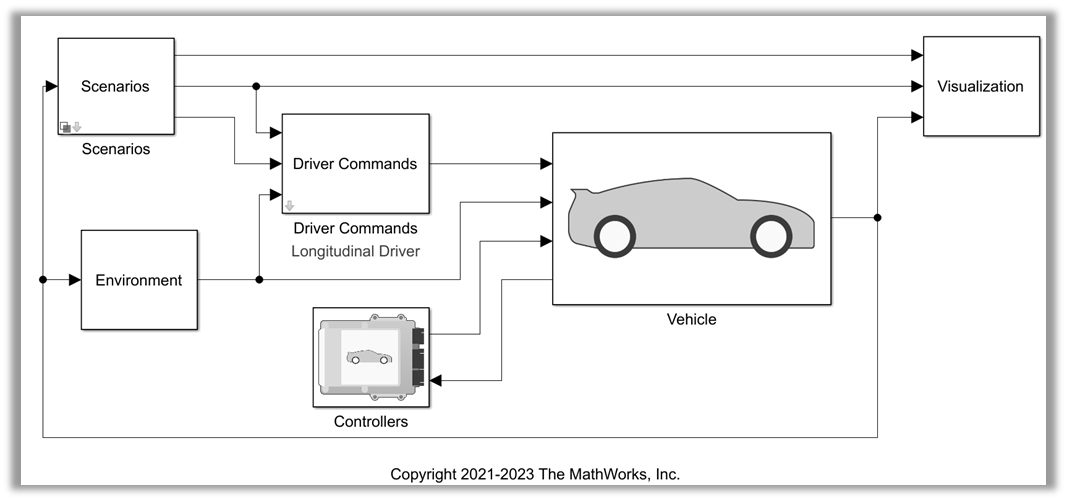

## Description

Introducing changes to the software of a vehicle is not trivial. Changes made to one component can affect other interconnected components within the vehicle; and understanding these changes requires thorough analysis of such interconnected systems. Such testing on actual vehicles can be a time-consuming study, especially when you have limited access to the vehicle. 

Developing a virtual replicate of the car allows you to conduct such studies, safely push the designs up to their limits without safety concerns. Scale up your simulation studies using cloud resources to explore the entire design space, and optimize design parameters after running iterative simulations studies quickly.

This allows you to effectively explore multiple design alternatives and produce the best design choice without being limited by hardware resources.

In this study, we examine the effect of changing

- the range and intensity of allowed regenerative braking, and

- the maximum allowable discharge current

When run through 3 separate drive cycles and examine the effect of doing so on the energy consumption, rate of SOC discharge and maximum acceleration achieved. We use this to determine how much we can adjust these parameters to enhance our vehicle using a set of software changes only.

## Building a Virtual Vehicle

In this example, we create the virtual vehicle for a 2-Motor Electric Passenger Vechicle, with the help of the [Virtual Vehicle Composer App](https://www.mathworks.com/help/autoblks/ref/virtualvehiclecomposer-app.html). The vehicle was specified to include a 340V battery pack (96s31p configuration), with the 2 motors sized to meet the potential needs of a typical passenger vehicle. 

    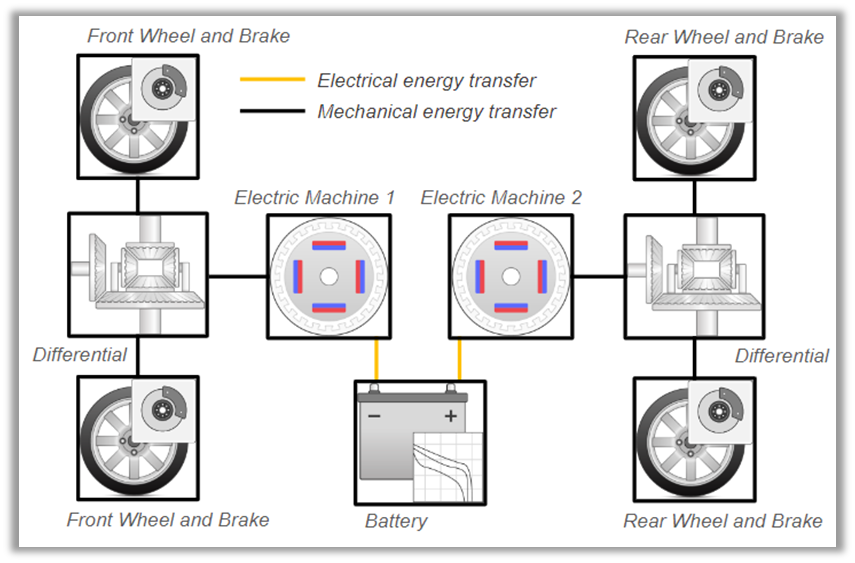

Learn more about how to develop a virtual vehcile model quickly here: [https://www.mathworks.com/videos/building-your-virtual-vehicle-simulation-with-simulink-1636386071631.html](https://www.mathworks.com/videos/building-your-virtual-vehicle-simulation-with-simulink-1636386071631.html) 

mdl = 'ConfiguredVirtualVehicleModel';
open_system(mdl)

    

Note that the Battery Management System (BMS) software was updated to incldue a custom built BMS:

    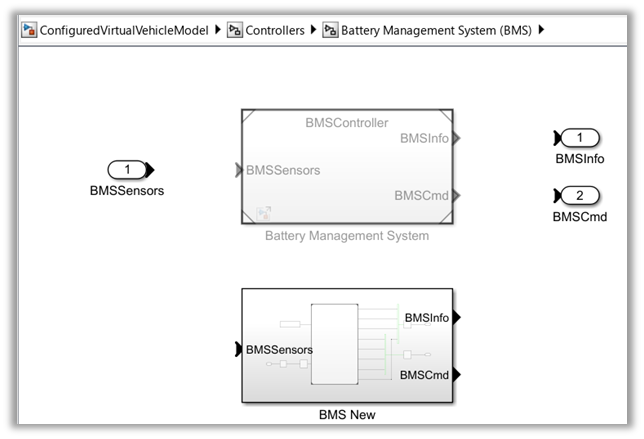

open_system('BMS_Software')

    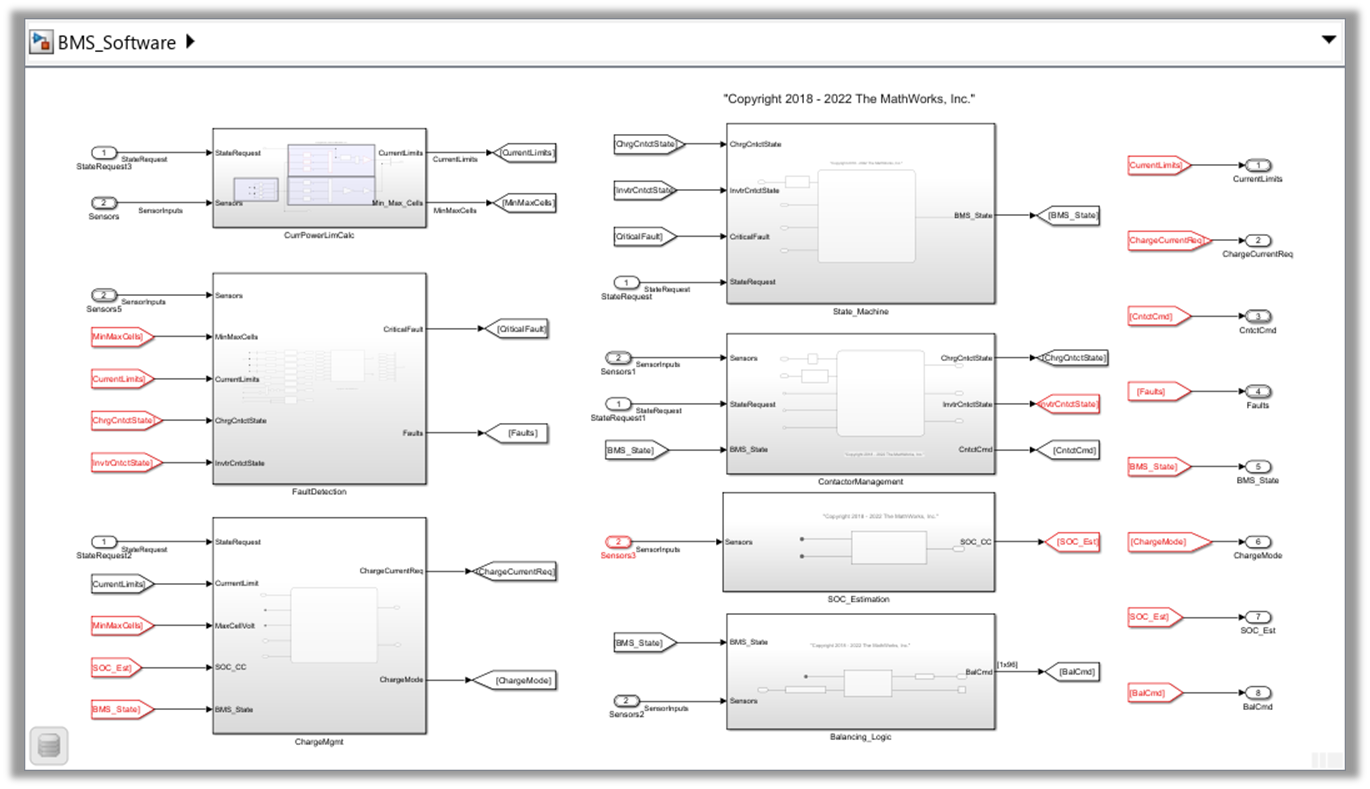

Feel free to inspect other controllers and componets of the model.

## Setup for a Multi-Simulation Study

### Simulate the model as is

Ensure the model can be opened, compiled and simulated without errors.

close_system('BMS_Software')

sim(mdl);

### Starting serial model reference simulation build.
### Successfully updated the model reference simulation target for: BMS_Software
### Model reference simulation target for DriverPassThrough is up to date.
### Model reference simulation target for EvPowertrainController2EM_r3_23a is up to date.
### Model reference simulation target for OpenLoopBraking is up to date.

Build Summary

Simulation targets built:

Model         Action                        Rebuild Reason                                                         
BMS_Software  Code generated and compiled.  Global variable #MaxSprtDchrgCurrLimit#BMS_Software_DD.sldd# changed.  

1 of 4 models built (3 models already up to date)
Build duration: 0h 0m 18.535s


Simulink.sdi.loadView(fullfile('Scripts','System Simulation Study','VirtualVehicleData.mldatx'))
Simulink.sdi.view

### Define inputs and variables that are changing

In this study, we will vary 3 parameters:

- The Input Drive Cycle

- Regen Operational Cutoff

- Maximum Discharge Current

        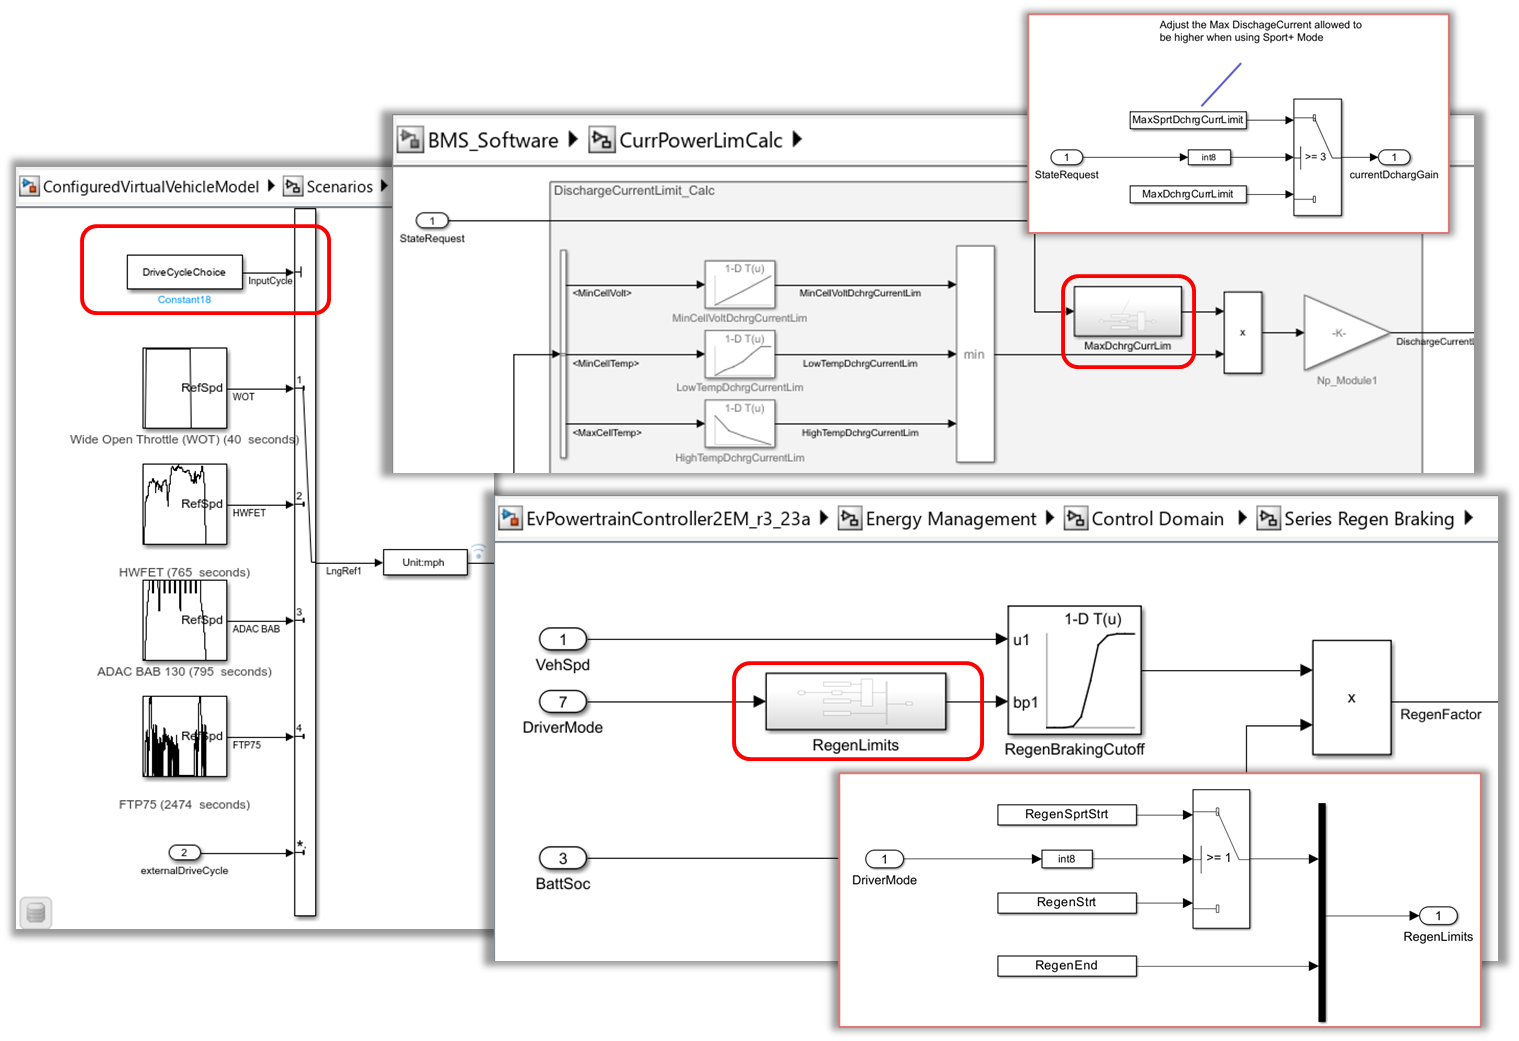

input_MaxDchrgCurrLimit = single(-12 : -0.5: -18)';
input_RegenStrt = (2:0.5:5)';
input_DriveCycleChoice = [1 2 3 4]';
input_DriveCycleChoiceTime = [40 765 795 2474]';

### Define simulation conditions for each simulation

Create [Simulink.SimulationInput](https://www.mathworks.com/help/simulink/slref/simulink.simulationinput-class.html) objects and specify the variables to be changed in each simulation. Add variables to be varied in each simulation into the Simulink.SimulationInput object.

runID = 1;
clear in
for v1 = 1:length(input_MaxDchrgCurrLimit)
    for v2 = 1:length(input_RegenStrt)
        for v3 = 1:length(input_DriveCycleChoice)
            
            in(runID) = Simulink.SimulationInput(mdl);
            blkName = 'ConfiguredVirtualVehicleModel/Driver Commands/DriverMode';
            in(runID) = in(runID).setBlockParameter(blkName,'Value', '1');

            in(runID) = in(runID).setVariable('MaxSprtDchrgCurrLimit',input_MaxDchrgCurrLimit(v1),'Workspace','global-workspace');
            in(runID) = in(runID).setVariable('RegenSprtStrt',input_RegenStrt(v2),'Workspace','global-workspace');
            in(runID) = in(runID).setVariable('DriveCycleChoice',input_DriveCycleChoice(v3),'Workspace','global-workspace');
            in(runID) = in(runID).setModelParameter("StopTime",num2str(input_DriveCycleChoiceTime(v3)));

            disp(['runID = ' num2str(runID) ';  MaxDischarge = ' num2str(input_MaxDchrgCurrLimit(v1)) ';  RegenStart = ' num2str(input_RegenStrt(v2)) ...
                ';  DriveCycle = ' num2str(input_DriveCycleChoice(v3)) ])
           
            runID = runID+1;
        end
    end
end

runID = 1;  MaxDischarge = -12;  RegenStart = 2;  DriveCycle = 1
runID = 2;  MaxDischarge = -12;  RegenStart = 2;  DriveCycle = 2
runID = 3;  MaxDischarge = -12;  RegenStart = 2;  DriveCycle = 3
runID = 4;  MaxDischarge = -12;  RegenStart = 2;  DriveCycle = 4
runID = 5;  MaxDischarge = -12;  RegenStart = 2.5;  DriveCycle = 1
runID = 6;  MaxDischarge = -12;  RegenStart = 2.5;  DriveCycle = 2
runID = 7;  MaxDischarge = -12;  RegenStart = 2.5;  DriveCycle = 3
runID = 8;  MaxDischarge = -12;  RegenStart = 2.5;  DriveCycle = 4
runID = 9;  MaxDischarge = -12;  RegenStart = 3;  DriveCycle = 1
runID = 10;  MaxDischarge = -12;  RegenStart = 3;  DriveCycle = 2
runID = 11;  MaxDischarge = -12;  RegenStart = 3;  DriveCycle = 3
runID = 12;  MaxDischarge = -12;  RegenStart = 3;  DriveCycle = 4
runID = 13;  MaxDischarge = -12;  RegenStart = 3.5;  DriveCycle = 1
runID = 14;  MaxDischarge = -12;  RegenStart = 3.5;  DriveCycle = 2
runID = 15;  MaxDischarge = -12;  RegenStart = 3.5;  DriveCycle = 3
runID

clear out ans  v1 v2 v3 runID

## Conduct the Multi-Simulation Study

### Running simulations one-by-one (with a small sample)

You can run the simulations in series on your own computer in series. Let us run 3 simulations as an example. 

inSeries = in(1:4);
tic
set_param(mdl, 'FastRestart', 'on')
outseries = sim(inSeries, 'ShowSimulationManager', 'on');

[02-Oct-2023 04:18:19] Running simulations...
### Starting serial model reference simulation build.
### Successfully updated the model reference simulation target for: BMS_Software
### Model reference simulation target for DriverPassThrough is up to date.
### Model reference simulation target for EvPowertrainController2EM_r3_23a is up to date.
### Model reference simulation target for OpenLoopBraking is up to date.

Build Summary

Simulation targets built:

Model         Action                        Rebuild Reason                                                         
BMS_Software  Code generated and compiled.  Global variable #MaxSprtDchrgCurrLimit#BMS_Software_DD.sldd# changed.  

1 of 4 models built (3 models already up to date)
Build duration: 0h 0m 17.603s
[02-Oct-2023 04:18:58] Completed 1 of 4 simulation runs
[02-Oct-2023 04:19:25] Completed 2 of 4 simulation ru

toc

Elapsed time is 200.461419 seconds.


Per the above example, the total time it would take to run large simulations studies can quickly escalate. 

### Running simulations at scale using Parallel Simulation spport (parsim and batchsim)

The parallel computing toolbox, and MATLAB parallel server products can help you scale up your studies, by simulating at the same time on different workers. `parsim` makes it easy for you to run the same model with different inputs or different parameter settings in scenarios such as Monte Carlo analyses, parameter sweeps, model testing, experiment design, and model optimization.

Setup your parallel environment referring to the following documentation [[1](https://www.mathworks.com/help/parallel-computing/run-code-on-parallel-pools.html)][[2](https://www.mathworks.com/help/parallel-computing/scale-up-from-desktop-to-cluster.html)]. Once you have that in place, you can run your simulations in parallel.

In parallel

tic
getStudyResults = 1;
switch getStudyResults
    case 1
        parpool('Processes');
        studyData = parsim(in,'ShowSimulationManager', 'on');
    case 2
        parpool('R23a_EvStudy');
        studyData = parsim(in(1:20),'ShowSimulationManager', 'on');
    case 3
        parpool('R23a_EvStudy');
        studyData = batchsim(in,'ShowSimulationManager', 'on');
    case 4
        load studyData.mat
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 24 workers.


[02-Oct-2023 04:22:20] Checking for availability of parallel pool...
[02-Oct-2023 04:22:20] Starting Simulink on parallel workers...
[02-Oct-2023 04:22:27] Loading project on parallel workers...
[02-Oct-2023 04:22:27] Configuring simulation cache folder on parallel workers...
[02-Oct-2023 04:22:41] Loading model on parallel workers...
[02-Oct-2023 04:23:26] Running simulations...
[02-Oct-2023 04:41:09] Cleaning up parallel workers...


clear getStudyResults ans
toc

Elapsed time is 1181.727612 seconds.


I ran this on my own Quad-Core laptop computer as a benchmark of how much time it takes to run such studies:

    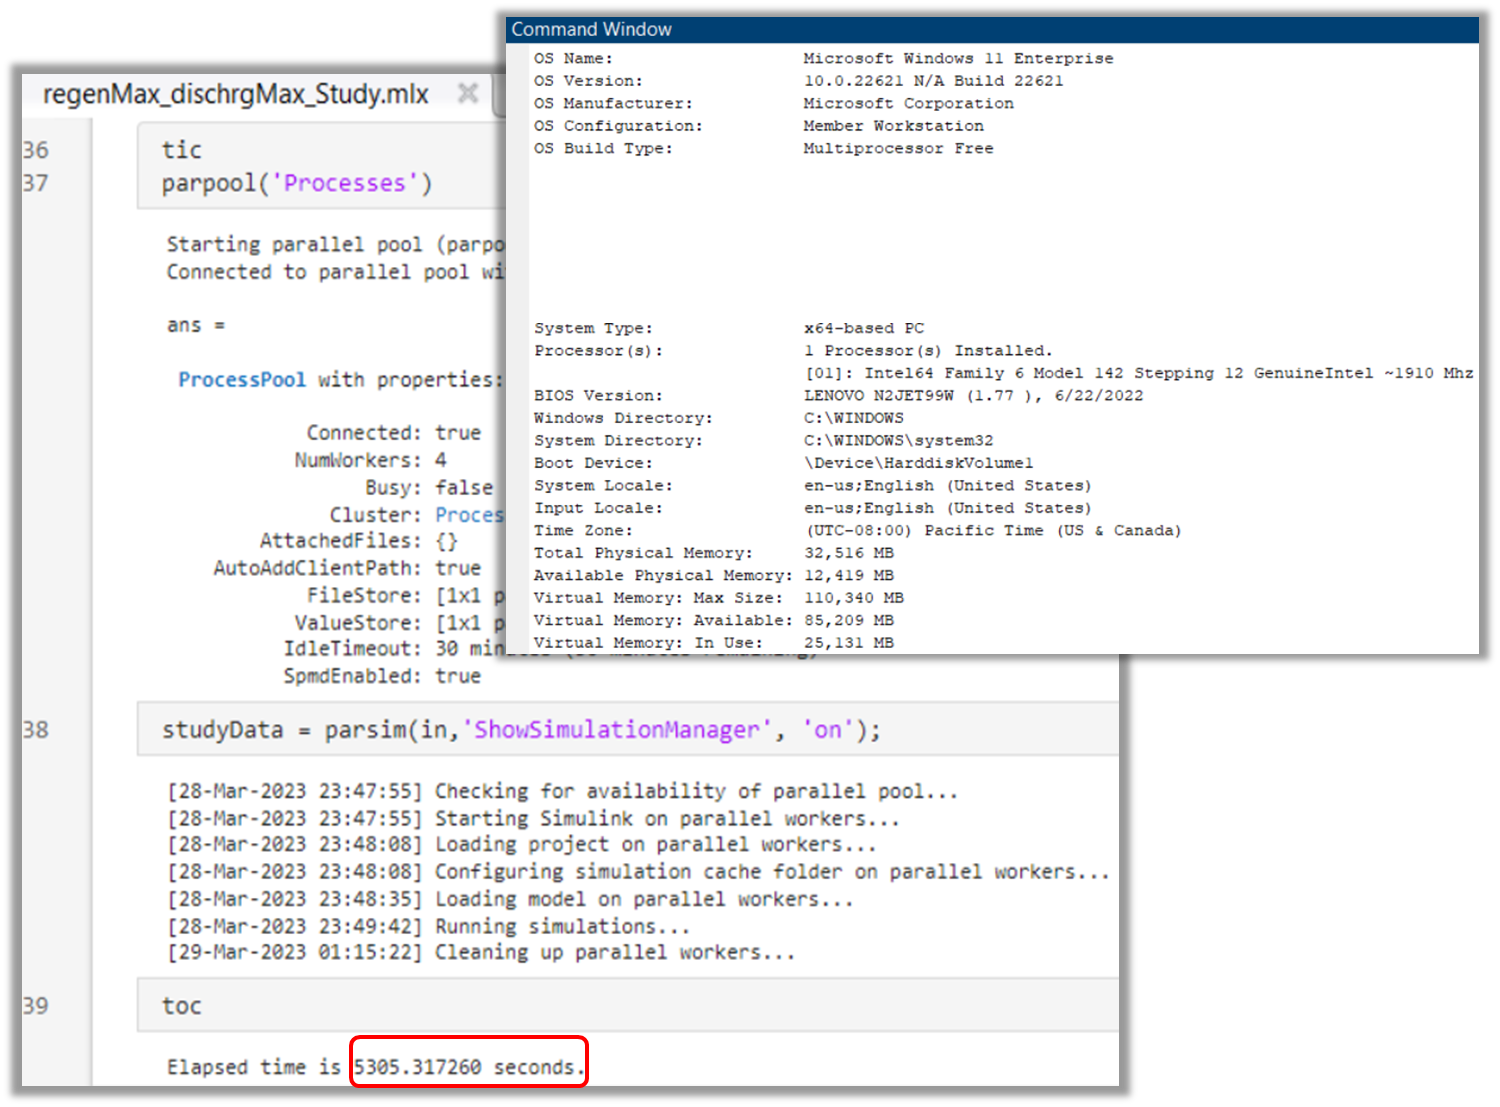

### Detailed review of the simulation time

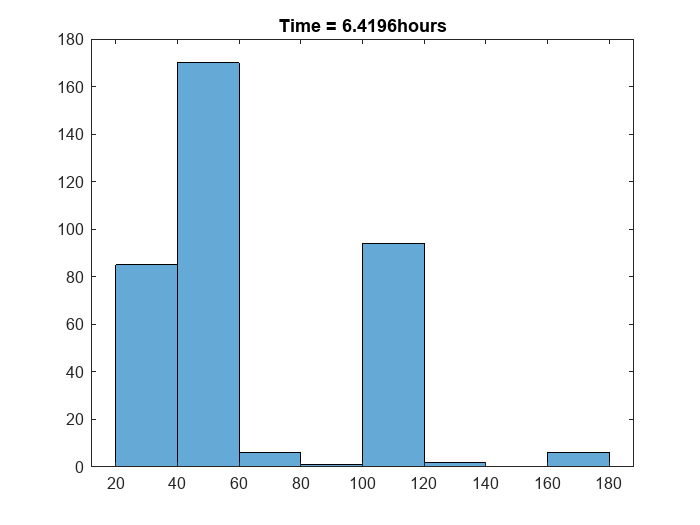

figure
totaltime = zeros(1,length(studyData));
for i = 1:length(studyData)
    totaltime(i) = studyData(i).SimulationMetadata.TimingInfo.TotalElapsedWallTime;
end
histogram(totaltime); title(['Time = ' num2str(sum(totaltime)/3600) 'hours'])

clear i totaltime

As you can see, the time taken to compelte this study is significantly shorter when you scale up using parallel workers.

## Review of the Simulation Results

Plot one of the results

plot(studyData(1,4))
Simulink.sdi.loadView(fullfile('Scripts','System Simulation Study','VirtualVehicleData.mldatx'))

### Reducing 0-60mph time

Inspect what happens when we vary the max allowed discharge current:

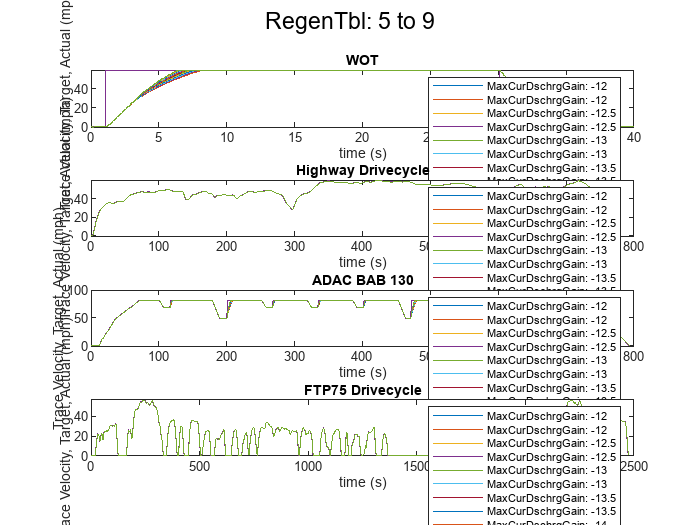

sigName = 'Trace Velocity, Target, Actual (mph)';
regenTbl_Low =5;
plotCommonRegenTbl(sigName,regenTbl_Low,studyData, input_MaxDchrgCurrLimit,input_RegenStrt);

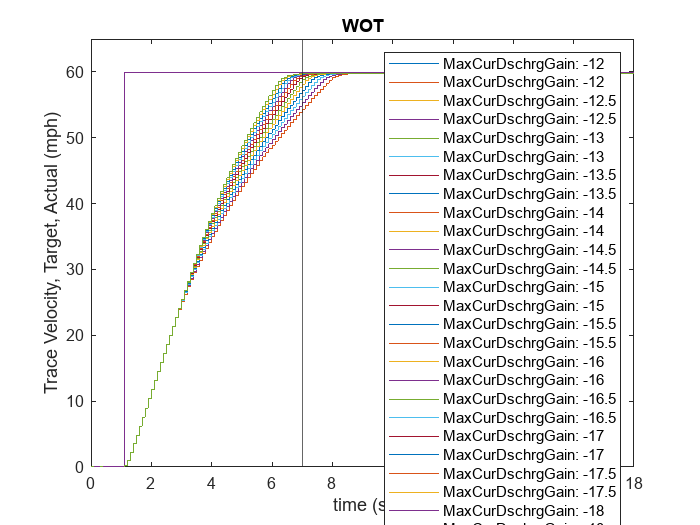

plotAccelerationUpdate(studyData, input_MaxDchrgCurrLimit,input_RegenStrt)

**        Examining the Wide-Open Throttle (WOT) test:**

- We can clearly see a gain in acceleration time with increased current discharge.

- Note how the at low speeds you are not limited by current or power, but limited by how much torque you are allowed to limit wheel speed at launch.  This is why the curves only start to deviate at higher speeds.

- From the figure, **Setting the discharge current gain to a factor of 17 or higher** results in a 0-60mph time of **under 6 seconds.**

### Effect of increasing your max current - reduced EV Range

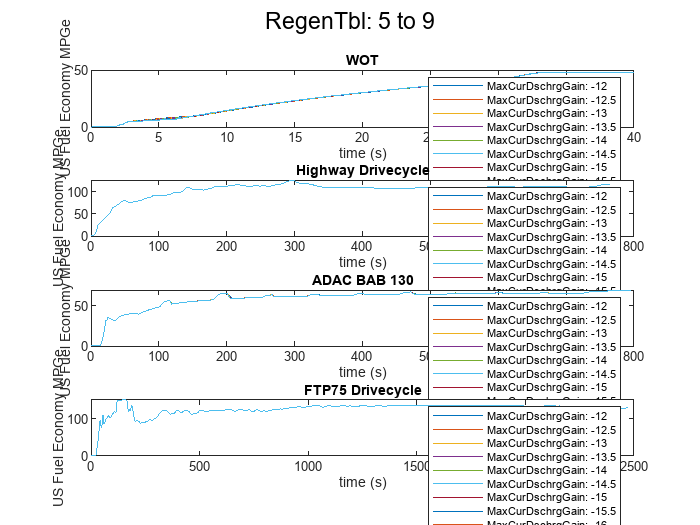

sigName = 'US Fuel Economy MPGe';
regenTbl_Low =5;
plotCommonRegenTbl(sigName,regenTbl_Low,studyData, input_MaxDchrgCurrLimit,input_RegenStrt);

- The increased current results in higher energy consumption, reducing the EV range on the WOT and ADAC drive cycles.

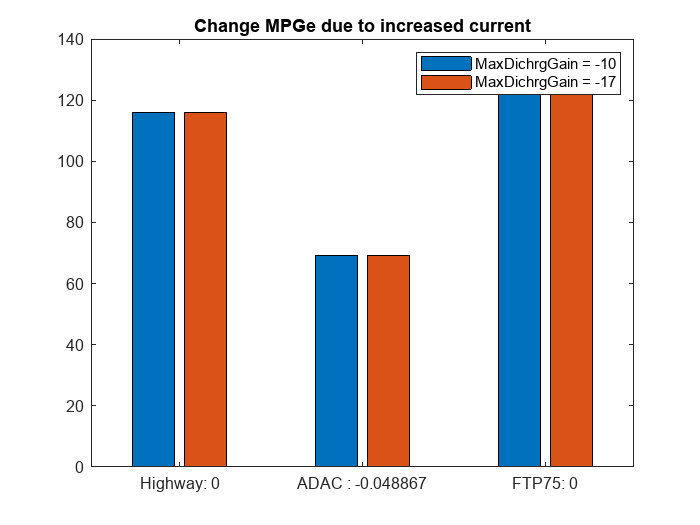

sigName         = 'US Fuel Economy MPGe';
baserun         = 25;  % Run Corresponding to RegenTblLow = 5; gainMaxDschrgCur = -10
highCurRun      = 221; % Run Corresponding to RegenTblLow = 5; gainMaxDschrgCur = -17
plotValChange(sigName,baserun,highCurRun,studyData)

A half percent may not look like much, but given the drive cycles are no longer than 15 minutes long, that value can quickly increase when using sport+ mode for sustained periods.

Can we compensate for the increased consumption by recovering additional energy during braking?

### Increasing EV Range

What does it mean to change the `regenTbl_Low` value? It means we can extend the range in which the regen is operational:

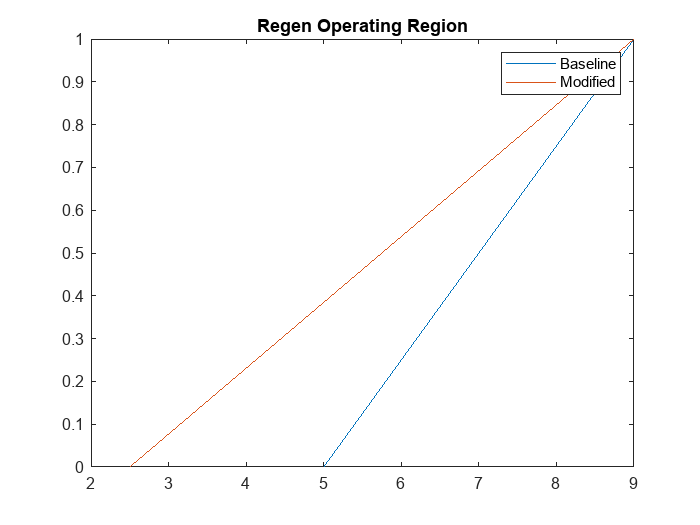

figure
plot([5,9],[0,1],[2.5,9],[0,1])
title('Regen Operating Region')
legend('Baseline','Modified')

Inspect the what happens when we vary the regen operational range:

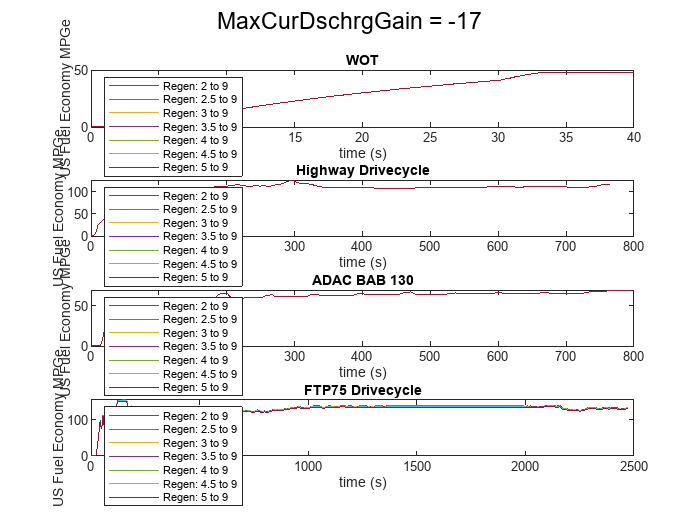

sigName = 'US Fuel Economy MPGe';
maxDischargeGain =-17;
plotCommonDischrg(sigName,maxDischargeGain, studyData, input_MaxDchrgCurrLimit,input_RegenStrt);

**        Examining the Changing MPGe in the figure above:**

- Highway cycles or cycles without a lot of braking do not see any gains from regen, so the MPGe stays the same.

- Hard braking, as seen in WOT or in city/traffic driving will show gains in MPGe.

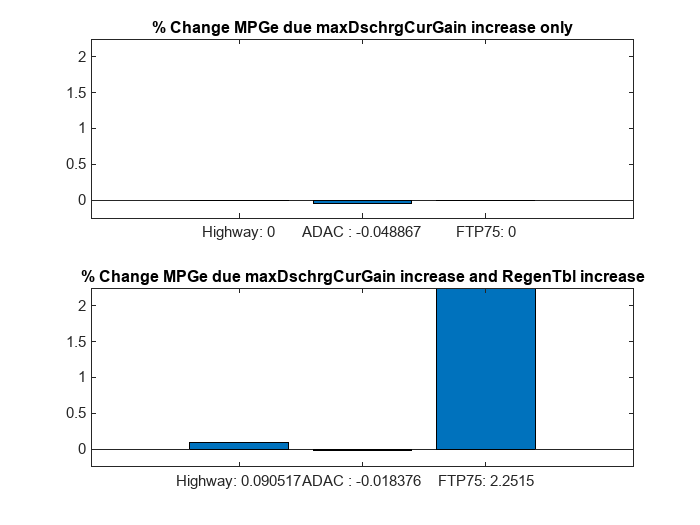

sigName         = 'US Fuel Economy MPGe';
baserun         = 25;   % Run Corresponding to RegenTblLow = 5; gainMaxDschrgCur = -10
highCurRun      = 221;  % Run Corresponding to RegenTblLow = 5; gainMaxDschrgCur = -17
highCurwRegenRun= 201;  % Run Corresponding to RegenTblLow = 2.5; gainMaxDschrgCur = -17
plotPrcntChange(sigName,baserun,highCurRun, highCurwRegenRun,studyData)

## **Inferences from the Study Data**

    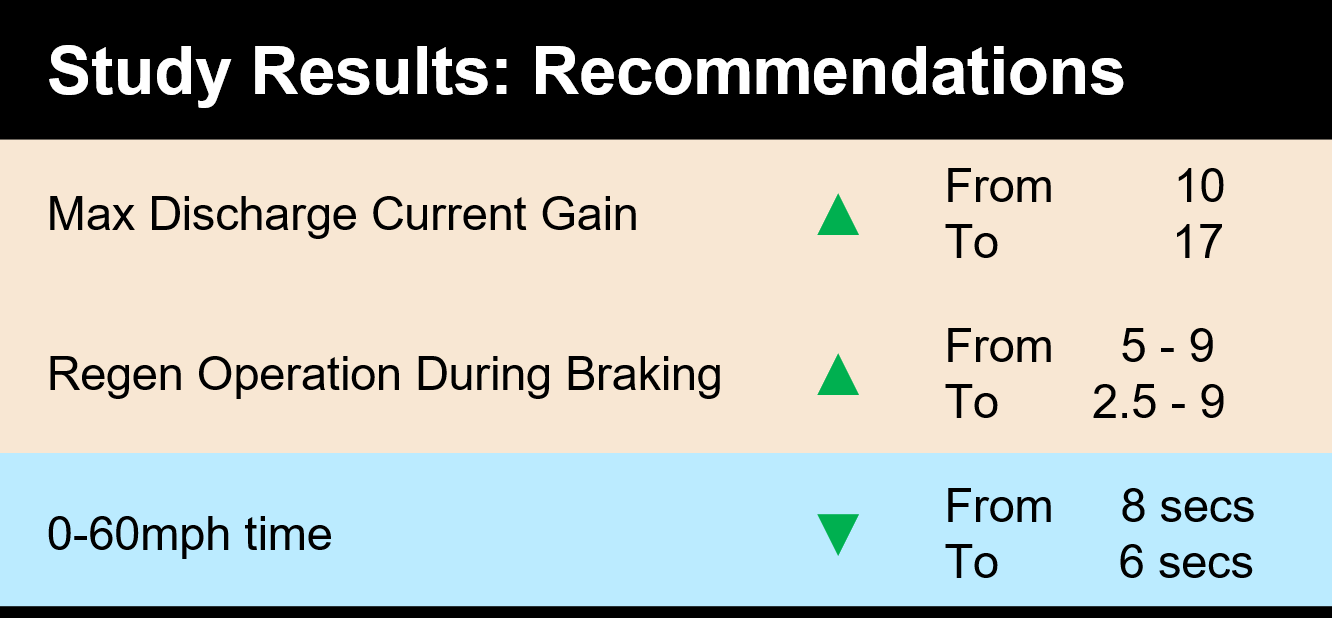

The results show:

- Increasing the allowed **discharge current by 70% can result in a 0-60 time of under 6 seconds.**

- The increased current results in higher energy consumption in high acceleration events.

- We can compensate for the MPGe reduction by enhancing the area of the RegenTbl operation, **reducing the regenLowLim from 5 to 2.5.**

### **3D surface plot of varying parameters**

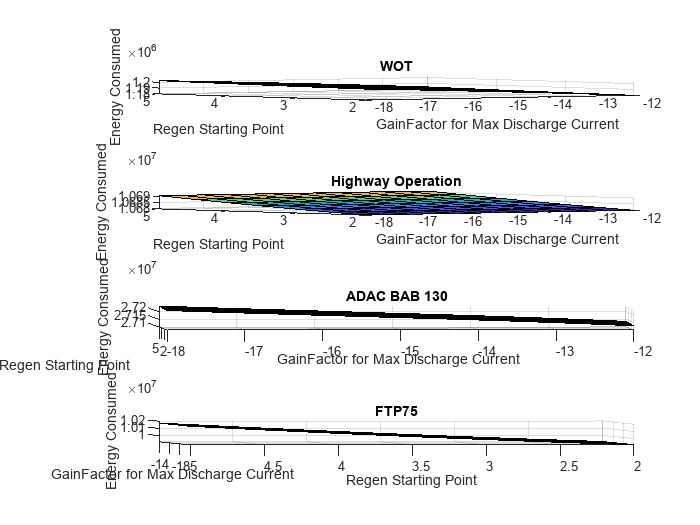

sigName = 'Energy Consumed';
plotMultiVar3d(sigName,studyData, input_MaxDchrgCurrLimit,input_RegenStrt)
subplot(4,1,3)
view([-1 8])
subplot(4,1,4)
view([-94 9])

## Additional: Helper Functions to Plot Study Results

function plotCommonDischrg(sigName,maxdischrgeGain, studyData, input_MaxDchrgCurrLimit,input_RegenStrt)
% This function generates multiple figures that show how varying the variable
% "Max Current Dischage Gain" affects the variable "signame"
% This fcn accounts for the 3 different drive cycles included in the simStudy
    runID = 1;
    rowID = 1;
    for v1 = 1:length(input_MaxDchrgCurrLimit)
        if input_MaxDchrgCurrLimit(v1) == maxdischrgeGain
            figure
            fullLegend = {};
            for v2 = 1:length(input_RegenStrt)
                sgtitle(['MaxCurDschrgGain = ' num2str(input_MaxDchrgCurrLimit(v1))])
                subplot(4,1,1)
                    plot(studyData(1,runID).logsout.getElement(sigName).Values)
                    title('WOT')
                    xlabel('time (s)')
                    ylabel(sigName)
                    hold on
                subplot(4,1,2)
                    plot(studyData(1,runID+1).logsout.getElement(sigName).Values)
                    title('Highway Drivecycle')
                    xlabel('time (s)')
                    ylabel(sigName)
                    hold on
                subplot(4,1,3)
                    plot(studyData(1,runID+2).logsout.getElement(sigName).Values)
                    title('ADAC BAB 130')
                    xlabel('time (s)')
                    ylabel(sigName)
                    hold on
                subplot(4,1,4)
                    plot(studyData(1,runID+3).logsout.getElement(sigName).Values)
                    title('FTP75 Drivecycle')
                    xlabel('time (s)')
                    ylabel(sigName)
                    hold on
                legendName = ['Regen: ' num2str(input_RegenStrt(v2)) ' to 9'];
                fullLegend = cat(1, fullLegend,legendName);
                rowID = rowID+1;
                runID = runID +4;
            end
            subplot(4,1,1); legend(fullLegend,"Location","northwest");
            subplot(4,1,2); legend(fullLegend,"Location","northwest");
            subplot(4,1,3); legend(fullLegend,"Location","northwest");
            subplot(4,1,4); legend(fullLegend,"Location","northwest");
        end
    end
end

function plotCommonRegenTbl(sigName,regenTbl_Low,studyData, input_MaxDchrgCurrLimit,input_RegenStrt)
% This function generates multiple figures that show how varying the variable
% "Regen Start Point" affects the variable "signame"
% This fcn accounts for the 3 different drive cycles included in the simStudy
    runIDx = 1:4:50;
    for v1 = 1:length(input_RegenStrt)
        if input_RegenStrt(v1)==regenTbl_Low
            figure
            fullLegend = {};
            runID = runIDx(v1);
            for v2 = 1:length(input_MaxDchrgCurrLimit)
                sgtitle(['RegenTbl: ' num2str(input_RegenStrt(v1)) ' to 9'])
                subplot(4,1,1)
                    plot(studyData(1,runID).logsout.getElement(sigName).Values)
                    title('WOT')
                    xlabel('time (s)')
                    ylabel(sigName)
                    hold on
                subplot(4,1,2)
                    plot(studyData(1,runID+1).logsout.getElement(sigName).Values)
                    title('Highway Drivecycle')
                    xlabel('time (s)')
                    ylabel(sigName)
                    hold on
                subplot(4,1,3)
                    plot(studyData(1,runID+2).logsout.getElement(sigName).Values)
                    title('ADAC BAB 130')
                    xlabel('time (s)')
                    ylabel(sigName)
                    hold on
                subplot(4,1,4)
                    plot(studyData(1,runID+3).logsout.getElement(sigName).Values)
                    title('FTP75 Drivecycle')
                    xlabel('time (s)')
                    ylabel(sigName)
                    hold on
                legendName = ['MaxCurDschrgGain: ' num2str(input_MaxDchrgCurrLimit(v2))];
                numDataSigs = size(studyData(1,runID).logsout.getElement(sigName).Values.data,2);
                for i = 1:numDataSigs
                    fullLegend = cat(1, fullLegend,legendName);
                end
                runID = runID + 28;
            end
            subplot(4,1,1); legend(fullLegend,"Location","northeast");
            subplot(4,1,2); legend(fullLegend,"Location","northeast");
            subplot(4,1,3); legend(fullLegend,"Location","northeast");
            subplot(4,1,4); legend(fullLegend,"Location","northeast");
        end
    end
end

function plotAccelerationUpdate(studyData, input_MaxDchrgCurrLimit,input_RegenStrt)
% This function generates multiple figures that show how varying the variable
% "Regen Start Point" affects the variable "signame"
% This fcn accounts for the 3 different drive cycles included in the simStudy
    sigName = 'Trace Velocity, Target, Actual (mph)';
    regenTbl_Low = 5;
    runIDx = 1:4:50;
    for v1 = 1:length(input_RegenStrt)
        if input_RegenStrt(v1)==regenTbl_Low
            figure
            fullLegend = {};
            runID = runIDx(v1);
            for v2 = 1:length(input_MaxDchrgCurrLimit)
                    plot(studyData(1,runID).logsout.getElement(sigName).Values)
                    title('WOT')
                    xlabel('time (s)')
                    xlim([0 18])
                    ylim([0 65])
                    ylabel(sigName)
                    hold on
                legendName = ['MaxCurDschrgGain: ' num2str(input_MaxDchrgCurrLimit(v2))];
                numDataSigs = size(studyData(1,runID).logsout.getElement(sigName).Values.data,2);
                for i = 1:numDataSigs
                    fullLegend = cat(1, fullLegend,legendName);
                end
                runID = runID + 28;
            end
            xline(7)
            legend(fullLegend,"Location","southeast");
        end
    end
end

function plotValChange(sigName,baserun,highCurRun,studyData)
    baseMPG_Highway         = studyData(1,baserun+1).logsout.getElement(sigName).Values.Data(end);
    baseMPG_ADAC            = studyData(1,baserun+2).logsout.getElement(sigName).Values.Data(end);
    baseMPG_FTP75           = studyData(1,baserun+3).logsout.getElement(sigName).Values.Data(end);
    newMPG_Highway          = studyData(1,highCurRun+1).logsout.getElement(sigName).Values.Data(end);
    newMPG_ADAC             = studyData(1,highCurRun+2).logsout.getElement(sigName).Values.Data(end);
    newMPG_FTP75            = studyData(1,highCurRun+3).logsout.getElement(sigName).Values.Data(end);
    pcChange_MPG_Highway    = (newMPG_Highway - baseMPG_Highway)/baseMPG_Highway * 100;
    pcChange_MPG_ADAC       = (newMPG_ADAC - baseMPG_ADAC)/baseMPG_ADAC * 100;
    pcChange_MPG_FTP75      = (newMPG_FTP75 - baseMPG_FTP75)/baseMPG_FTP75 * 100;
    figure
        bar([baseMPG_Highway newMPG_Highway; baseMPG_ADAC newMPG_ADAC; baseMPG_FTP75 newMPG_FTP75])
        xticklabels({['Highway: ' num2str(pcChange_MPG_Highway)],['ADAC : ' num2str(pcChange_MPG_ADAC)],['FTP75: ' num2str(pcChange_MPG_FTP75)]})
        legend({'MaxDichrgGain = -10','MaxDichrgGain = -17'})
        title('Change MPGe due to increased current')
end

function plotPrcntChange(sigName,baserun,highCurRun, highCurwRegenRun,studyData)
    baseMPG_Highway         = studyData(1,baserun+1).logsout.getElement(sigName).Values.Data(end);
    baseMPG_ADAC            = studyData(1,baserun+2).logsout.getElement(sigName).Values.Data(end);
    baseMPG_FTP75           = studyData(1,baserun+3).logsout.getElement(sigName).Values.Data(end);
    newMPG_Highway          = studyData(1,highCurRun+1).logsout.getElement(sigName).Values.Data(end);
    newMPG_ADAC             = studyData(1,highCurRun+2).logsout.getElement(sigName).Values.Data(end);
    newMPG_FTP75            = studyData(1,highCurRun+3).logsout.getElement(sigName).Values.Data(end);
    lastMPG_Highway         = studyData(1,highCurwRegenRun+1).logsout.getElement(sigName).Values.Data(end);
    lastMPG_ADAC            = studyData(1,highCurwRegenRun+2).logsout.getElement(sigName).Values.Data(end);
    lastMPG_FTP75           = studyData(1,highCurwRegenRun+3).logsout.getElement(sigName).Values.Data(end);
    pcChange1_MPG_Highway   = (newMPG_Highway - baseMPG_Highway)/baseMPG_Highway * 100;
    pcChange1_MPG_ADAC      = (newMPG_ADAC - baseMPG_ADAC)/baseMPG_ADAC * 100;
    pcChange1_MPG_FTP75     = (newMPG_FTP75 - baseMPG_FTP75)/baseMPG_FTP75 * 100;
    pcChange2_MPG_Highway   = (lastMPG_Highway - baseMPG_Highway)/baseMPG_Highway * 100;
    pcChange2_MPG_ADAC      = (lastMPG_ADAC - baseMPG_ADAC)/baseMPG_ADAC * 100;
    pcChange2_MPG_FTP75     = (lastMPG_FTP75 - baseMPG_FTP75)/baseMPG_FTP75 * 100;
    figure
    subplot(2,1,1)
        bar([pcChange1_MPG_Highway; pcChange1_MPG_ADAC; pcChange1_MPG_FTP75])
        ylim([-0.25 2.25])
        xticklabels({['Highway: ' num2str(pcChange1_MPG_Highway)],['ADAC : ' num2str(pcChange1_MPG_ADAC)],['FTP75: ' num2str(pcChange1_MPG_FTP75)]})
        title('% Change MPGe due maxDschrgCurGain increase only')
    subplot(2,1,2)
        bar([pcChange2_MPG_Highway; pcChange2_MPG_ADAC; pcChange2_MPG_FTP75])
        ylim([-0.25 2.25])
        xticklabels({['Highway: ' num2str(pcChange2_MPG_Highway)],['ADAC : ' num2str(pcChange2_MPG_ADAC)],['FTP75: ' num2str(pcChange2_MPG_FTP75)]})
        title('% Change MPGe due maxDschrgCurGain increase and RegenTbl increase')
end

function plotMultiVar3d(sigName,studyData, input_MaxDchrgCurrLimit,input_RegenStrt)
% This function generates 3D figures that show how varying the both variables
% "Max Current Dischage Gain"  and "Regen Start Point" affects the end value of the variable "signame"
% This fcn accounts for the 3 different drive cycles included in the simStudy
    runID = 1;
    rowID = 1;
    for v1 = 1:length(input_MaxDchrgCurrLimit)
        for v2 = 1:length(input_RegenStrt)
            sigVal(rowID,1) = studyData(1,runID).logsout.getElement(sigName).Values.Data(end);
            sigVal(rowID,2) = studyData(1,runID+1).logsout.getElement(sigName).Values.Data(end);
            sigVal(rowID,3) = studyData(1,runID+2).logsout.getElement(sigName).Values.Data(end);
            sigVal(rowID,4) = studyData(1,runID+3).logsout.getElement(sigName).Values.Data(end);
            rowID = rowID+1;
            runID = runID +4;
        end
    end
    [X,Y] = meshgrid(input_MaxDchrgCurrLimit,input_RegenStrt);
    
    figure
    subPltTitles = {'WOT','Highway Operation','ADAC BAB 130','FTP75'};
    for i = 1:4
        Z = reshape(sigVal(:,i),length(input_RegenStrt),length(input_MaxDchrgCurrLimit));
        subplot(4,1,i)
        surf(X,Y,Z)
        xlabel('GainFactor for Max Discharge Current ')
        ylabel('Regen Starting Point')
        zlabel(sigName)
        title(subPltTitles{i})
    end
end